# Confidence Configuration Using Range Finder Recordings

In this script, I shall extract the optimal confidence weights using the collected range finder data(which was used for template optimization).  

Each range finder recording has an IR and PSNR value. The duty cycle and max val can be calculated for each chunk of the recorded data.

The following steps will be performed:

- Apply the previously calculated confidence to each chunk and See how the result fits the accuracy:

                                    Average confidence in respect to the z-accuracy.

                                    ROC curve and AUC.

                                    Per confidence, how much chunks were classified correctly and how much weren’t(red green bar plot). 

        2.  Retrain the confidence params using the range finder data **without** the psnr. Compare the results.

        3.  Retrain the confidence params using the range finder data **with** the psnr. Compare the results.

## Current Configuration Evaluation On Range Finder Data

In this section the previously calculated confidence will be applied to each chunk and then examined. 

## Build the training data. For each chunk we end with [d.c., psnr,maxVal,ir] and [sampleGT, sampleEst,zGT,zAcc]

% Load default regs to use when mimicking some hw blocks
% [fw,p] = Pipe.loadFirmware();
% [regs,luts] = fw.get();

%% Load all of the RF data. Average 9 consecutive recordings and represent the data as a Nx4 matrix.
recordingsPath = 'X:\Data\IvCam2\NN\DCOR\IRFullRange8G';
rangeDirs = dir(recordingsPath);
rangeDirs = rangeDirs(3:end);
rangeDirs = rangeDirs([rangeDirs.isdir]);%rangeDirs: Contains a list of the directories - each directory has the recordings for a specific range of psnr/ir

% Define the constant sample rate, code length and binary code:
sampleRate = 8;
codeLen = 64;
tmplLength = codeLen*sampleRate;
binary = kron(Codes.propCode(codeLen,1),ones(sampleRate,1));% Get the transmitted code
C = 3*10^8; % Light speed
avgFactor = 1;

confInputData = []; % Will hold the input data for confidence training.[DC,psnr,max_val,IR]
confDataGT = []; % Holds [sGT,sEst]

for i= 1:numel(rangeDirs)
   fprintf('Proccesing data in dir: %s \n',rangeDirs(i).name)
   records = dir(fullfile(recordingsPath,rangeDirs(i).name) );
   records = records(3:end);
   records = records(~[records.isdir]);
   for j = 1:numel(records)
       matFilePath = fullfile(recordingsPath,rangeDirs(i).name,records(j).name);
       load(matFilePath);
       
       % average each 9 chunks of recordings
       data = cell2mat(arrayfun(@(i) mean(example.dataShiftedAug(:,i:i+avgFactor-1),2),1+(0:size(example.dataShiftedAug,2)/avgFactor-1)*avgFactor,'UniformOutput',false));
       
       %-------------------------------------------------%
       % Calculate the DC value as done in the RAST block:
       cma = data*(2^7-1); % Scale to 0-127.
       cmaSum = sum(cma, 1, 'native');
       dcCodeNorm = uint64(single(2^22)/single(tmplLength));
       dcLevel = int16(regs.RAST.dcLevel);
       imgTxRx = zeros(size(cmaSum));
       imgDcLevel = map(dcLevel, imgTxRx+1);
       diffDC = min(63, abs(int16(bitshift((uint64(cmaSum)*dcCodeNorm), -22))-imgDcLevel));
       lutConf = regs.RAST.confDC;
%        lutConf = uint8([15 15 15 15 15 15 15 15 15 15 15 15 15 15 14 14 14 14 14 14 14 14 14 13 13 13 12 12 11 10 9 8 7 6 5 4 3 3 2 2 2 1 1 1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0]);
       dutyCycle = map(lutConf, diffDC+1);
       %-------------------------------------------------%
       % Calculate the PSNR value:
       psnr = example.psnr*ones(size(dutyCycle),'uint8');
       %-------------------------------------------------%
       % Calculate the IR value:
       ir = bitshift(uint16(example.irMean), -int8(regs.DCOR.irLUTExp))*ones(size(dutyCycle),'uint16');
       %-------------------------------------------------%
       % Calculate the max val value:
       cma_ = double(min(63, bitshift(uint16(cma+1),-1)));
       corr = Utils.correlator(cma_, 7*binary);
       [maxValOrig,mI] = max(corr);
       maxValOrig = uint32(maxValOrig);
       % Quantize the peak result
       C = double(regs.FRMW.corSaturationPrc);% of max to saturate to maximum
       maxPeakVal = 2^6-1;
       N_TMPLT_BITS=3;
       N_CMA_BITS = 6;
       al1 = @(n) 2^n-1;
       maxvalDiv = uint32(4*maxPeakVal*2^14/(C*al1(N_TMPLT_BITS)*al1(N_CMA_BITS)*double(tmplLength)));
       maxvalSub = uint32(maxPeakVal/C);
       maxVal  = uint8(min(maxPeakVal,bitshift(maxValOrig*maxvalDiv,-14)-maxvalSub));
       %-------------------------------------------------%
       % Calculate the sGT value:
       sGT = arrayfun(@(i) mean(example.dataShiftedAugIgt(:,i:i+avgFactor-1),2),1+(0:size(example.dataShiftedAugIgt,2)/avgFactor-1)*avgFactor);
       %-------------------------------------------------%
       % Calculate the sEst value:
       pFit = @(c) parabFit(c)-1;
       sEst = arrayfun(@(i) pFit(corr(:,i)),1:size(corr,2));
       %-------------------------------------------------%
       % Calculate the zGT:
       zGT = example.z*ones(size(dutyCycle));
       %-------------------------------------------------%
       % Calculate the zAcc:
       zErr = abs(sGT-sEst)*3*10^8/(2*sampleRate*10^9)*1000;% In mm
       zRE = zErr./zGT*100;% In percentage
       %-------------------------------------------------%
       % Add the data:
       confInputData = [confInputData,[dutyCycle;psnr;maxVal;ir]];%[DC,psnr,max_val,IR]
       confDataGT = [confDataGT,[sGT;sEst;zErr;zRE]];%[sGT,sEst]
   end
end

Proccesing data in dir: psnr_25 
Proccesing data in dir: psnr_33 
Proccesing data in dir: psnr_43 
Proccesing data in dir: psnr_47 
Proccesing data in dir: psnr_49 
Proccesing data in dir: psnr_51 
Proccesing data in dir: psnr_53 
Proccesing data in dir: psnr_55 
Proccesing data in dir: psnr_57 


%% Save the data in order to save running time in the future
% save('tmp\trainingData.mat','confInputData','confDataGT')

## Classifier Performance

Now we shall apply the classifier to our data and get a sense of its performance.

## Load the data

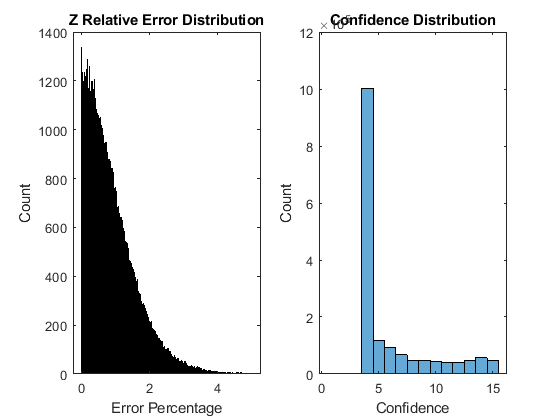

% load('tmp\trainingData.mat')

%% Load the current weights configuration:
regs.DEST.confIRbitshift = uint8(6); % confIRbitshift determines which 6 bits to use from the 
regs.DEST.confw1 = [int8(30),int8(0),int8(127),int8(-56)]; % Calculated scaled weights value. 
regs.DEST.confw2 = [int8(0),int8(0),int8(0),int8(0)]; % Other weights path should be ignored.
regs.DEST.confv = [int8(0),int8(0),int8(0),int8(0)]; % All biases are zero.
regs.DEST.confq = [int8(1),int8(0)];% Keep the first channel. Zero the second.
dt = int16(13419); x0 = int16(-3528); % Activation maps [minPrev,maxPrev]->[-128,127]. dt and 
regs.DEST.confactIn = [x0,dt];
dt = int16(255); x0 = int16(-128);% Activation maps [-128,127]->[0,255]. dt and x0 are calculated 
regs.DEST.confactOt = [x0,dt];

dutyCycle4b = confInputData(1,:);
psnr6b  = 0*confInputData(2,:);
maxPeak6b  = confInputData(3,:);
ir  = confInputData(4,:);
confOut = Pipe.DEST.confBlock( dutyCycle4b, psnr6b, maxPeak6b,ir,  regs );

% Show the distribution of the accuracy and of the confidence
figure;
subplot(1,2,1)
zRE = confDataGT(4,:);
histogram(zRE,0:0.001:5)
title('Z Relative Error Distribution'),xlabel('Error Percentage'), ylabel('Count')
subplot(1,2,2)
histogram(confOut,0.5:15.5)
title('Confidence Distribution'),xlabel('Confidence'), ylabel('Count')

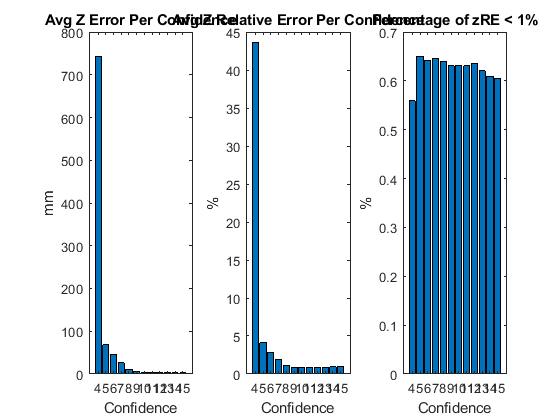


% Per confidence, show the average z error, average z relative error, the percentage of pixels with RE less than 0.3%.
confVals = unique(confOut);
avgZErr = zeros(size(confVals));
avgZRE = zeros(size(confVals));
precZRE = zeros(size(confVals));
zErr = confDataGT(3,:);
zRE = confDataGT(4,:);
for i = 1:numel(confVals)
    avgZErr(i) = mean(zErr(confOut==confVals(i))); 
    avgZRE(i) = mean(zRE(confOut==confVals(i))); 
    precZRE(i) = mean(zRE(confOut==confVals(i))<1);
end
figure
subplot(1,3,1)
bar(confVals,avgZErr)
title('Avg Z Error Per Confidence')
xlabel('Confidence')
ylabel('mm')
subplot(1,3,2)
bar(confVals,avgZRE)
title('Avg Z Relative Error Per Confidence')
xlabel('Confidence')
ylabel('%')
subplot(1,3,3)
bar(confVals,precZRE)
title('Percentage of zRE < 1%')
xlabel('Confidence')
ylabel('%')

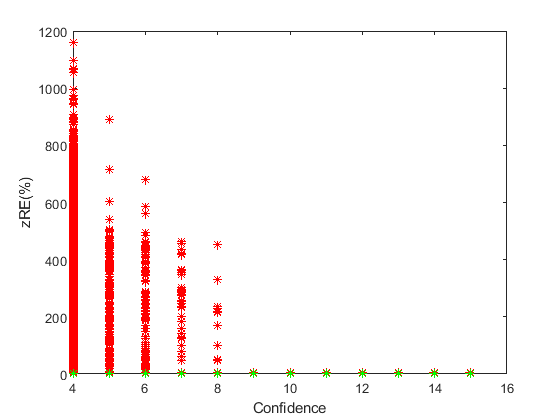


% Plot the distribution of the z error per confidence
[logits_sort,order] = sort(confOut);
depthErrorSort = zRE(order);
labels = zRE<1;
labelsSort = labels(order);
figure
plot((logits_sort(labelsSort==0)),depthErrorSort(labelsSort==0),'r*' )
hold on 
plot((logits_sort(labelsSort==1)),depthErrorSort(labelsSort==1),'g*' )
xlabel('Confidence'); ylabel('zRE(%)');
hold off

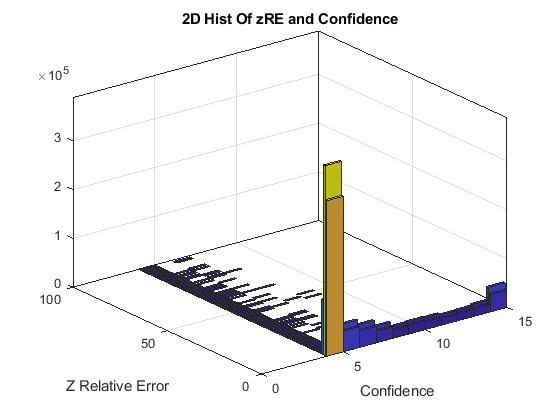

% Show as a histogram:
histogram2(confOut,zRE,0:15,0:100,'FaceColor' ,'flat')
xlabel('Confidence')
ylabel('Z Relative Error')
title('2D Hist Of zRE and Confidence')

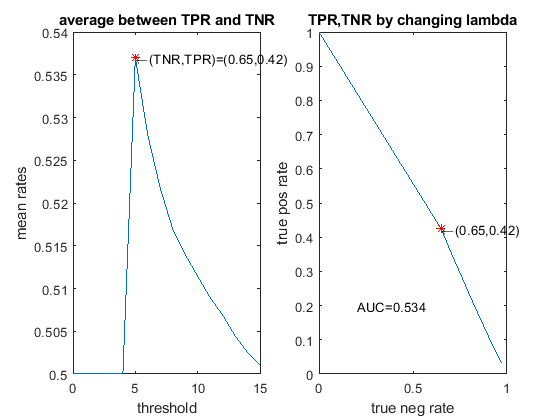


% ROC Curve and AUC
th = 0:15;
labels = zRE <=1;
true_pos_rate = zeros(size(th));
true_neg_rate = zeros(size(th));
for i = 1:numel(th)
    true_pos_rate(i) = sum((confOut>=th(i)) .* labels) ./ sum(labels);
    true_neg_rate(i) = sum((confOut<th(i)) .* (1-labels)) ./ sum(1-labels);
end
figure
subplot(1,2,1)
mean_rate = mean([true_pos_rate;true_neg_rate]);
plot(th,mean_rate); xlabel('threshold');ylabel('mean rates');title('average between TPR and TNR');
[maxv,I] = max(mean_rate);
txt = strcat('\leftarrow', sprintf('(TNR,TPR)=(%.2f,%.2f)',true_neg_rate(I),true_pos_rate(I)));
text(th(I),mean_rate(I),txt)
hold on
plot(th(I),mean_rate(I),'r*')
t = th(I);
subplot(1,2,2)
plot(true_neg_rate,true_pos_rate); xlabel('true neg rate');ylabel('true pos rate');title('TPR,TNR by changing lambda');
AUC = trapz(true_neg_rate,true_pos_rate);
text(0.2,0.2,sprintf('AUC=%.3f',AUC))
hold on
plot(true_neg_rate(I),true_pos_rate(I),'r*')
txt = strcat('\leftarrow', sprintf('(%.2f,%.2f)',true_neg_rate(I),true_pos_rate(I)));
text(true_neg_rate(I),true_pos_rate(I),txt)

## Training a new configuration for the range finder data:

% load('tmp\trainingData.mat')

randOrd = randperm(size(confInputData,2));
confInputData = confInputData(:,randOrd);
confDataGT = confDataGT(:,randOrd);

pred = confInputData';
resp = confDataGT(4,:)'<=1;

dutyCycle = pred(:,1);
psnr = pred(:,2);
maxVal = pred(:,3);
ir = pred(:,4);
labels = confDataGT(4,:)' <= 1; 
T = table(dutyCycle,psnr,maxVal,ir,labels);
[trainedClassifier, validationAccuracy] = trainClassifier(T);

w = trainedClassifier.GeneralizedLinearModel.Coefficients.Estimate;
getScores = @(x) w(1) + x*(w(2:end));
scores = getScores(single(pred));
[X,Y,T,AUC] = perfcurve(resp,scores,1);
AUC

AUC = 0.5385

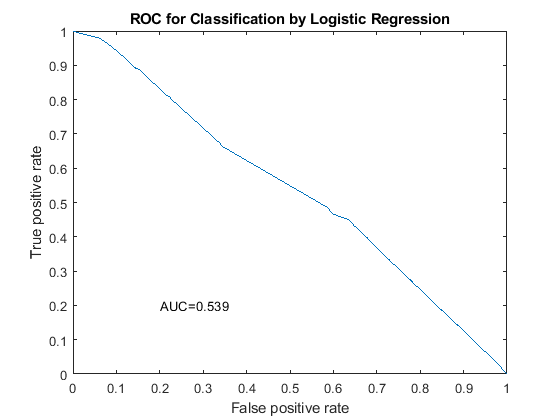

figure
plot(1-X,Y)
text(0.2,0.2,sprintf('AUC=%.3f',AUC))
xlabel('False positive rate')
ylabel('True positive rate')
title('ROC for Classification by Logistic Regression')

# TODO

- Look at the max val per chunk plot. there are many many zeros. Why? take a look...